# Metodo delle tangenti di Newton

Xk+1 = Xk - f(Xk) / f'(Xk)

## Definizione degli zeri

## Teorema

## Teorema

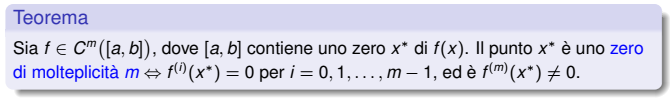

## Condizioni per la convergenza GLOBALE di Newton

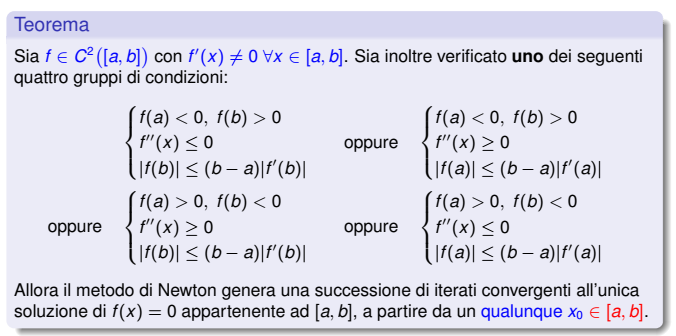

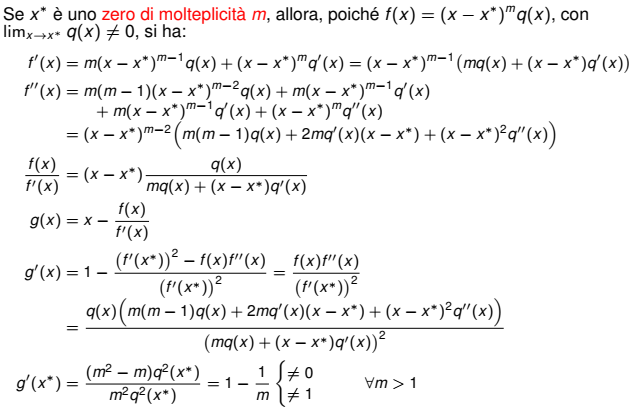

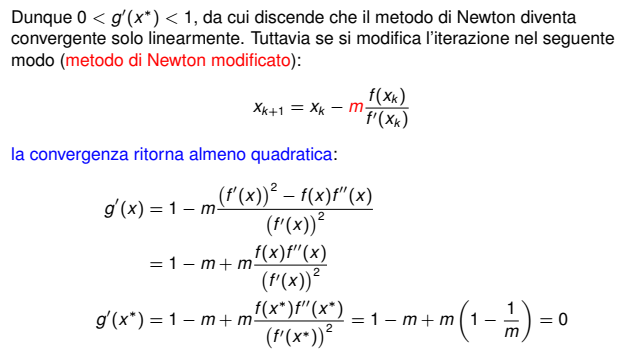

f = @(x) ((exp(x/2)/2)-x)

f = function_handle with value:
    @(x)((exp(x/2)/2)-x)


fp = @(x) ((exp(x/2)/4)-1)

fp = function_handle with value:
    @(x)((exp(x/2)/4)-1)



a = 4;
b = 5;

c = (a+b)/2;
n = 4;
v = zeros(n,1);

v(1)=c;

for i=2:n
    v(i) = v(i-1) - f(v(i-1))/fp(v(i-1));
end

disp(v);

    4.5000
    4.3222
    4.3067
    4.3066




fs = @(x) (exp(x/2)/8);

costAsintErr = @(x) (fs(x)/(2 * fp(x)));

disp(costAsintErr(v(n)));

    0.4668

